## EJERCICIO 1


RS = 8.56;
RP = 141.8;

Paralel = RP*(RS + 50);
SumParalel = RP +RS+ 50;

par = (Paralel/SumParalel)

par = 41.4444

Zil = RS + (Paralel/SumParalel)

Zil = 50.0044


S11 = (Zil-50)/(Zil+50)

S11 = 4.4398e-05

S11dB = 20*log10(S11)

S11dB = -87.0527

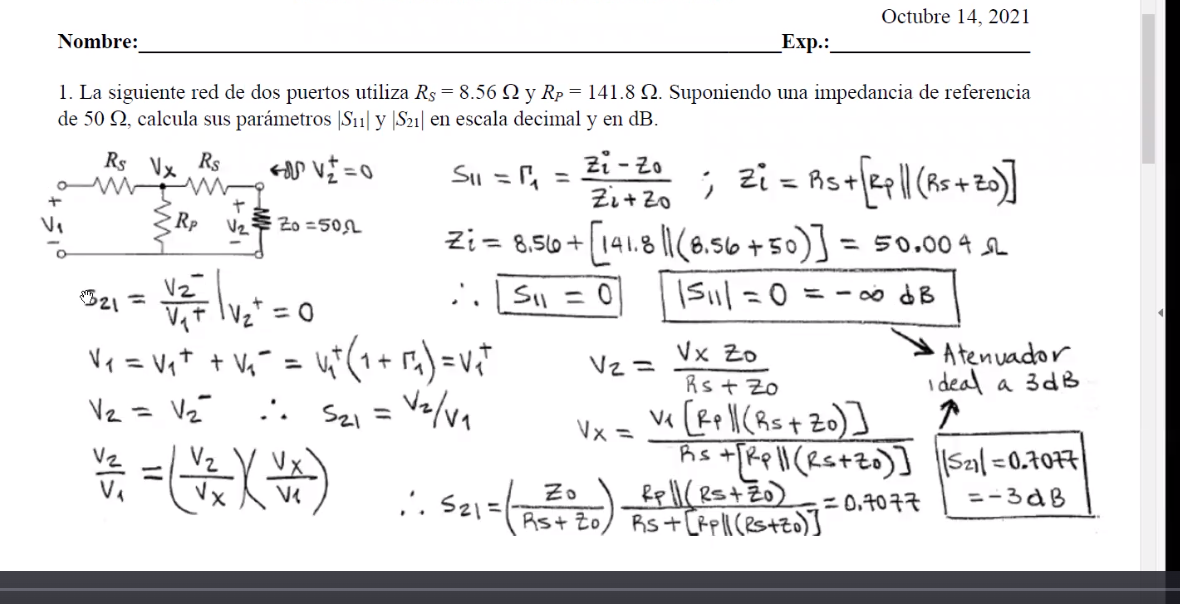


S21_1 = (50*(Paralel/SumParalel))/((RS + 50)*(RS + (Paralel/SumParalel)))

S21_1 = 0.7077

S21 = (1-S11)*S21_1

S21 = 0.7076

S21dB = 20*log10(S21)

S21dB = -3.0039


Z12 = RS + (par)

Z12 = 50.0044

%z12 = RS + (1 / ((1/RP)+(1/(RS+50))))
S22 = (Z12-50)/(Z12+50)

S22 = 4.4398e-05

S22dB = 20*log10(S22)

S22dB = -87.0527



S12 = (1+S22)*((50*(par))/((RS+50)*(RS+(par))))

S12 = 0.7077

S12dB = 20*log10(S12)

S12dB = -3.0031

## EJERCICIO 2


Rs = 1.25;
N=20;
w = 2*pi*60;
vp= 0.3e9;
B=w/vp;
z0 = 75;
l=380e3;
BL = B*l;

Rl = 82;
Ll = 65e-3;
zl = Rl+1j*w*Ll;

Vs= 110;

RsParam = [1 Rs;0 1];
TransfParam = [-1/N 0;0 -N];
LineParam = [cos(BL) 1j*z0*sin(BL); 1j*(1/z0)*sin(BL) cos(BL)];
RlLl = [1 0; 1/zl 1];

ABCDT = RsParam*TransfParam*LineParam*RlLl

ABCDT =   -0.2987 - 0.0982i -22.2034 - 1.7234i
  -0.1989 - 0.0631i -17.7627 + 0.0000i



VL = Vs/ABCDT(1,1)

VL = -3.3230e+02 + 1.0923e+02i

magVL = abs(VL)

magVL = 349.7896

angleVL = angle(VL)*180/pi

angleVL = 161.8032


IS = VL*ABCDT(2,1)

IS = 72.9762 - 0.7447i

magIS = abs(IS)

magIS = 72.9800

angleIS = angle(IS)*180/pi

angleIS = -0.5847



res = 61/2020 + 1j*81/101

res = 0.0302 + 0.8020i

magRes = abs(res)

magRes = 0.8025

angleRes = angle(res)*180/pi

angleRes = 87.8436

## EJERCICIO 3



S11complex = -0.05;
S12complex = (9*sqrt(2))/20 + 1j*(9*sqrt(2))/20;
S21complex = (9*sqrt(2))/20 + 1j*(9*sqrt(2))/20;
S22complex = -1j/10;

Puerto1 = S11complex + S12complex*(S21complex/(1-S22complex))

Puerto1 = 0.0302 + 0.8020i


magn = abs(Puerto1)

magn = 0.8025

anglet = angle(Puerto1)*180/pi

anglet = 87.8436